# Scrivo le equazioni di Hill aggiungendo tre variabili ausiliarie

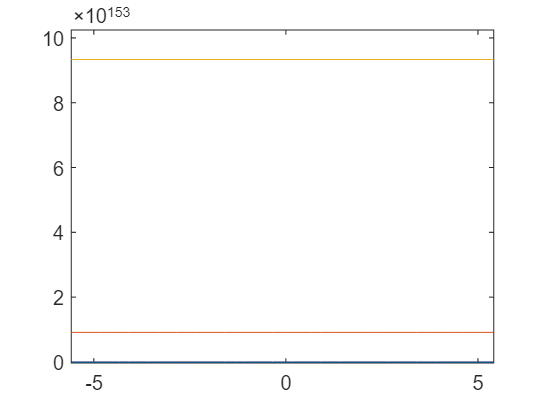

t0=0; tf= 50;
N=100;
h=(tf-t0)/N;

Fx= 328;
Fy=789;
Fz=348;

w0=23;

mc=2392832;
y(1)= 0;
x(1)=0;
z(1)=0;

a(1)= 1;
b(1)=1;
c(1)=1;
for k= 1:100
    x(k+1)=x(k)+h*a(k);
    a(k+1)= a(k) + (Fx/mc)*h + 2*w0*c(k);

    y(k+1) = y(k) + b(k)*h;
    b(k+1) = b(k) + (Fy/mc)*h + -w0*y(k);

    z(k+1)= z(k) + c(k)*h;
    c(k+1)= c(k) + (Fz/mc) *h - 2*w0* a(k) + 3* (w0^2)*z(k);

end

figure(1)

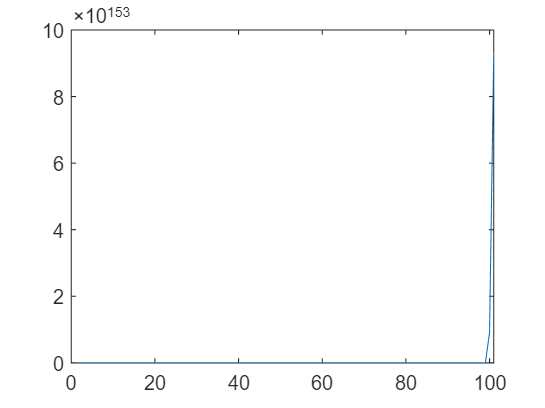

plot(x)

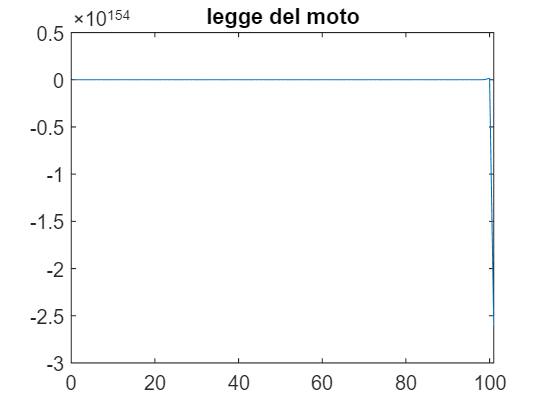

plot(z)
title('legge del moto')